Alexander Faust

ECE - 435 Homework 2 - Spectral Domain OCT

# Part I - Guiding Computations

% List System parameters:
clc; clear; close all;

lamb_0 = 1310 * 1e-9;                   % Center wavelength [m]
delta_lamd = 100 * 1e-9;                % Bandwidth [m]

                                        % Numerical aperture of lens: range of angles
NA = 0.055;                             % over which system can accept light
% List 'n' to imply data taken in air environment
n = 1;
                                        
dz = 2.7*10^(-6);

% Compute lateral resolution: describes how well the beam can be focused

res_lateral = 0.37 * lamb_0 / NA;

% Compute axial resolution:
res_axial = 2 * log10(2) * lamb_0^2 / (pi * delta_lamd);


% Compute B-scan aspect ratio:

width_b = 1*10^-3;

num_samples = 2048 ;

num_backgroud_Bscan = 175;

 
%without Accounting for Mirror Image Artifact

leftover = num_samples - num_backgroud_Bscan;

aspect1 = width_b / leftover;

%with Accounting for Mirror Imageaspec Artifact

aspect2 = width_b / num_samples;


# Part II - A Scan Function

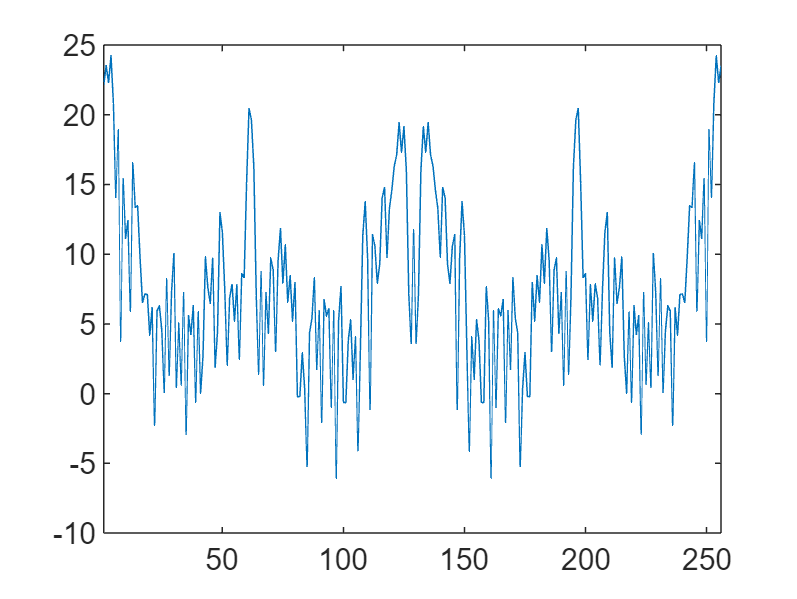

% Retrieve B scan data from file:
FID_B = fopen("BScan_Layers.raw");
data_B = fread(FID_B);

% Retrieve A scan data from file:
FID_A = fopen("Mscan1.raw");
data_A1 = fread(FID_A);

% Load the lambda to k-domain information matrix:
load("L2K.mat");

% Pack the data into vectors of length 2048 corresponding to each pixel's
% corresponding wavelength:
num_background_Bscan = 175;
num_background_Mscan1 = 320;
num_background_Mscan40 = 320;

data_B_matrix = reshape(data_B, [num_samples, length(data_B) / num_samples]);
background_data_B_matrix = data_B_matrix(:, 1 : num_background_Bscan);
A_scan_matrix = data_B_matrix(:, num_background_Bscan + 1 : end);

% Create function that generates complex A-scans in the spatial domain:
% NOTE: include background subtraction, windowing, & deconvolution

[Ascan, ~, ~] = generateAscan(num_samples, background_data_B_matrix, 256, 800, A_scan_matrix(:,6), L2K, 'blackman');
figure;
plot(1:256, 20*log10(abs(Ascan)));
xlim([1 256]);

# Part III - The B Scan

figure;
imshow(data_B);

function [A_full_pipeline, A_witho_deconv_and_sub, A_witho_deconv] = generateAscan( ...
    num_samples, background_scans, window_length, window_start_index, A_scan, L2K, window_type)

    % 1) Convert background scans to K domain, THEN average the background scans:
    % background_vector = data(1 : num_background_scans * num_samples);
    % background_scans = reshape(background_vector, [num_samples, length(background_vector) / num_samples]);
    background_scans_K = L2K * background_scans;
    % Average:
    avg_background_scans = mean(background_scans_K, 2);

    % Perform 2nd order polynomial fit of the averaged background scans
    coeff = polyfit(1 : num_samples, avg_background_scans, 2);
    avg_background_fitted = polyval(coeff, 1 : window_length)';

    % 2) Convert the given A scan to K domain:
    A_witho_deconv_and_sub = L2K * A_scan;

    % 3) Subtract averaged background scans from A scan:
    A_witho_deconv = A_witho_deconv_and_sub - avg_background_scans;
    
    % 4) Multiply the subtracted background scans by a user specified window:
    window = windowFunction(window_length, window_type);
    A_scan_K_windowed = A_witho_deconv(window_start_index : window_start_index + window_length - 1) .* window;
    
    % 5) Perform deconvolution: i.e. divide the windowed signal by the
    %    background scans:
    deblur_scan = A_scan_K_windowed ./ avg_background_fitted;
    
    % 6) Take an FFT:
    A_full_pipeline = fft(deblur_scan);

    % 7) Average the fft_scan result:
    %A_full_pipeline = A_scan_fft ./ (sum(norm(A_scan_fft)) / window_length)
end

function window = windowFunction(window_length, window_type)
    % Generate a window function of the specified type
    switch lower(window_type)
        case 'hamming'
            window = hamming(window_length);
        case 'hann'
            window = hann(window_length);
        case 'blackman'
            window = blackman(window_length);
        % Add more window types as needed
        otherwise
            error('Unsupported window type');
    end
end

function B_scan = generateBscan(A_scan_matrix)

end
